load('benchmarkstability.mat');
load('stabilitycanshu.mat');

进行缩聚

13：第三层横向位移

21：物理子结构转角

26：第二层横向位移

27：第一层横向位移

29：物理子结构另一个转角（此转角不受控）

index1 = [13,21,26,27,29];
index2 = [1:12,14:20,22:25,28];

Mm = M(index1,index1);
Mms = M(index1,index2);
Km = K(index1,index1);
Kms = K(index1,index2);
Ks = K(index2,index2);
Ksm = K(index2,index1);
Cm = C(index1,index1);
Cms = C(index1,index2);

Mmn = MNrt(index1,index1);
Mmsn = MNrt(index1,index2);
Kmn = KNrt(index1,index1);
Kmsn = KNrt(index1,index2);
Ksn = KNrt(index2,index2);
Ksmn = KNrt(index2,index1);
Cmn = CNrt(index1,index1);
Cmsn = CNrt(index1,index2);

KP = K-KNrt;
CP = C-CNrt;
MP = M-MNrt;

Mmp = MP(index1,index1);
Mmsp = MP(index1,index2);
Kmp = KP(index1,index1);
Kmsp = KP(index1,index2);
Ksp = KP(index2,index2);
Ksmp = KP(index2,index1);
Cmp = CP(index1,index1);
Cmsp = CP(index1,index2);

Kre = (Km-Kms*(Ks\Ksm));
Mre = (Mm-Mms*(Ks\Ksm));Mre(2,2) = 1e-6;Mre(5,5) = 1e-6;
Cre = (Cm-Cms*(Ks\Ksm));

Kren = (Kmn-Kmsn*(Ksn\Ksmn));
Mren = (Mmn-Mmsn*(Ksn\Ksmn));
Cren = (Cmn-Cmsn*(Ksn\Ksmn));

Krep = Kmp; % 物理子结构的自由度已经被包括在主自由度中了
Mrep = Mmp;
Crep = Cmp;

计算CR积分算法的$\alpha$

dt = 1/1024;
al = (4*Mre+2*dt*Cre+dt^2*Kre)\(4*Mre);

pid控制传递函数

P = 1.5;
I = 40;
D = 1e-8;
N = 1000;
s = tf('s');
Gp0 = P+I/s+D*N/(1+N/s);
%Gp0 = P+I/s+D*s;
Gp = [Gp0,0;0,Gp0];

然后是作动器传递函数G

Gc = ss(A_cplant,B_cplant,C_cplant,D_cplant);

参考输入经过Gp再经过Gs，得到的结果负反馈回参考输入

G0 = series(Gp,Gc);
G1 = feedback(G0,eye(2));

定义增益矩阵，将物理子结构2维扩展为5维

k1 = zeros(5,2);
k1(1,1) = 1;
k1(2,2) = 1;
k2 = zeros(5,3);
k2(3,1) = 1;
k2(4,2) = 1;
k2(5,3) = 1;

k4 = k1-k2*inv(Koo)*Kot;

k3 = zeros(5,5);
k3(4,1) = 1;
k3(2,2) = 1;
k3(5,3) = 1;

k6 = zeros(2,5);% 输入5维位移，取其中物理子结构的位移和转角
k6(1,4) = 1;
k6(2,2) = 1;
M5 = M_phys_5dof;
C5 = C_phys_5dof;
K5 = K_phys_5dof;

连续情况下的传递函数

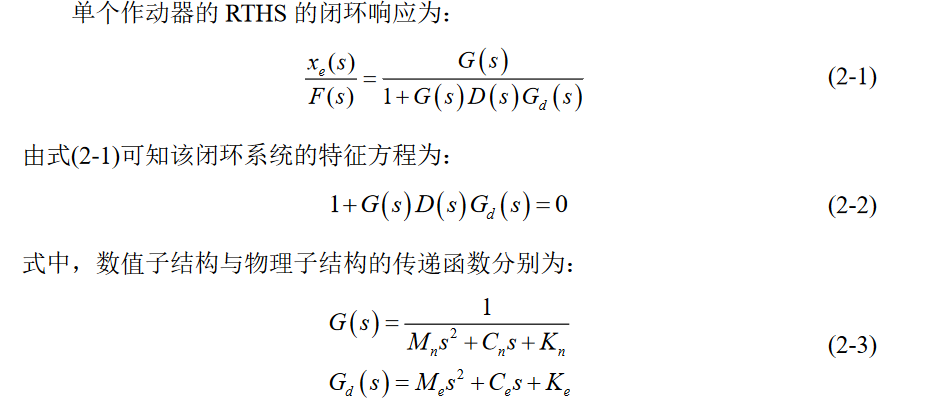

Gs = (Mren*s^2+Cren*s+Kren)\eye(5);

物理子结构中，x（5维）经过增益矩阵k6得到xa（2维）再经过控制器作动器得到xm（2维）

xm（2维）经过增益矩阵k4得到xm_5dof（5维），经过M_5dof,C_5dof,K_5dof得到fm（5维）

fm其中的3项（2、4、5）反馈回数值子结构

x到xa有，xa = k6*x

[A_G1, B_G1, C_G1, D_G1] = ssdata(G1);
Ds = ss(A_G1, B_G1*k6, C_G1, D_G1*k6);
Gd = k3*(M5*s^2+C5*s+K5)*k4;
Gd1 = series(Ds,Gd);
Gcl = feedback(Gs,Gd1);% 此即为连续时间下的整体状态空间方程
Gcl_m = minreal(Gcl);% 化简

199 states removed.


Gcl_d = c2d(Gcl_b,1/1024); % 离散
Gcl_tf = tf(Gcl_m);% 连续时间下传递函数
Gcl_tfd = tf(Gcl_d);% 离散时间下传递函数

求行列式

[num,den] = tfdata(Gcl_tf, 'v');
sym x;
x = sym('x');
Gcl4s = x*ones(5);
for d1 = 1:5
    for d2 = 1:5
        Polynum = poly2sym(num(d1,d2), x);
        Polyden = poly2sym(den(d1,d2), x);
        Gcl4s(d1,d2) = Polynum/Polyden;
    end
end
Gcl4s = vpa(Gcl4s,32);
detGs = det(Gcl4s);
solGs = solve(detGs);
max(real(solGs))

$$ans = 3416144451748.0918526589842936277$$

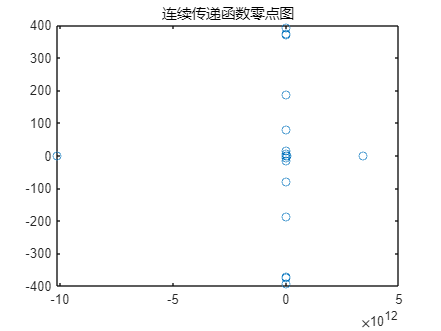

figure;
plot(real(solGs),imag(solGs),'o');
title('连续传递函数零点图')


[num,den] = tfdata(Gcl_tfd, 'v');
sym x;
x = sym('x');
Gcl4 = x*ones(5);
%Gcl3 = c2d(Gcl3s,dt,'tustin');
for d1 = 1:5
    for d2 = 1:5
        Polynum = poly2sym(num(d1,d2), x);
        Polyden = poly2sym(den(d1,d2), x);
        Gcl4(d1,d2) = Polynum/Polyden;
    end
end

detG = vpa(det(Gcl4),32);
solG = solve(detG == 0,x);
Gzero1= max(abs(solG))

$$Gzero1 = 10.451453036824648910553212019258$$

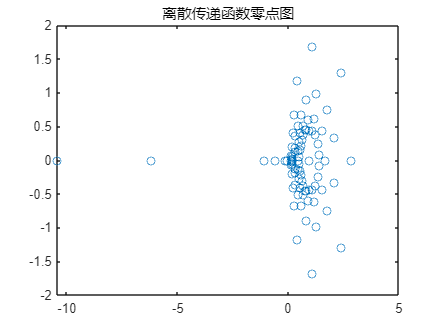

figure;
plot(real(solG),imag(solG),'o');
title('离散传递函数零点图')